if all(real(polos)<0)
    disp('Estable')
end

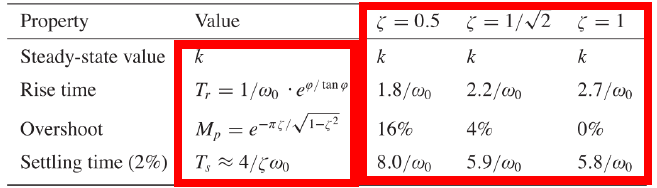

Mp       = 0.20;                         % Overshoot de 20% max
delta    = log(Mp);                      % Decremento logarítmico
zeta_val = 1/sqrt(1 + (pi/delta)^2);     % Relación de amortiguamiento crítico
disp(['zeta = ', num2str(zeta_val)])
Ts  = 2;                                 % Settling time de 2 sec
w_n = 4/(Ts*zeta_val);
disp(['omega_n = ', num2str(w_n), ' rad/s'])
sos = tf([w_n^2],[1 2*zeta_val*w_n w_n^2]); % Second-order system

Gc_sym_v1 = collect((kp + ki/s + kd*s)/poly2sym(A, s)) % Con el filtro de los ceros como la teoría
Gr_sym(i) = collect(Gc1_sym_aux*Gp_sym/(1 + Gp_sym*Gc_sym(i)), s);
[num, den] = numden(Gr_sym(i));
w          = coeffs(den, s, 'All');
w          = sum(w(end-2:end).*s.^[2 1 0])
num        = simplify(num/Gc1_sym_aux);
Gc1_sym(i) = w/num;

vars_all = symvar(eqs);
vars_sym = vars_all(arrayfun(@(v) isa(v, 'sym'), vars_all));
sol      = solve(eqs, vars_sym, 'ReturnConditions', true);
t    = 0:0.01:10;
ramp = t;
lsim(Gr(1), ramp, t); grid on;

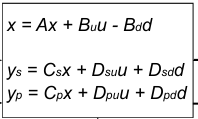

W = [B A*B A^2*B A^3*B A^4*B];
rank(W)

sys = ss(A-B*K, B1(:,2), C, [0;0]);
K = acker(A, Bu, [p1 p2 p3])
kr = 1/(Cp*(-(A-Bu*K)\Bu))

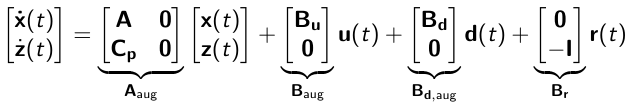

 

 

Aaug = [A  zeros(m, 1)
         C      0     ];
Baug = [B; 0];
Kaug  = acker(Aaug, Baug, [p1 p2 p3]);

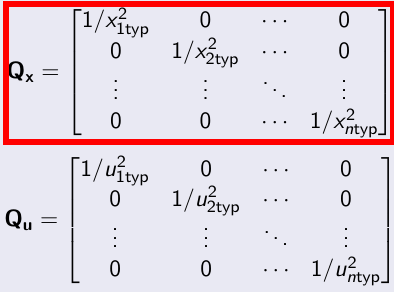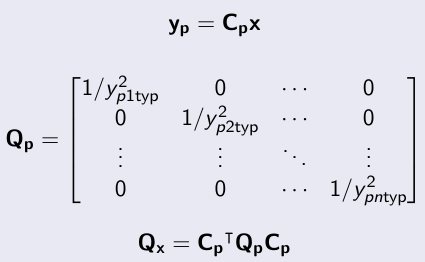

tDisplacement   = Displacement.time;
DisplacementVal = Displacement.signals.values;

Cpaux  = [Cp; A(2,:)];
Qy     = [1/(ytyp^2) 0
            0        1/(y2typ^2)];
Qx     = Cpaux'*Qy*Cpaux
u     = 1/(utyp^2);

[K, S] = lqr(A, Bu, Qx, Qu);




ytyp   = vtyp*  0.4; % Velocidad angular típica.
y2typ  = acctyp*0.2; % Aceleración angular tpipica.
errtyp = 0.1;         % Integral del error típica
utyp   = 400*   0.2;  % Nm engine torque typical.

Qyaug   = [1/(ytyp^2)      0          0
            0        1/(y2typ^2)      0
            0             0       1/(errtyp^2)];
Cpauxaug = [Cpaux zeros(2, 1)
            0     0    0    1];
Qxaug    = Cpauxaug'*Qyaug*Cpauxaug
eig([Qxaug zeros(4, 1); zeros(1, 4) Qu]) % caso aumentado
[Kaug, S] = lqr(Aaug, Baug, Qxaug, Qu); % por alguna razón no se puede
K         = Kaug(1:end-1)
ki = Kaug(end)


figure;
plot(tControlSignalMonitor, ControlSignal, 'LineWidth', 1.5);
xlabel('Tiempo [s]');
ylabel('Señal de control [u: N/m]');
title('Señal de control aplicada');
grid on;